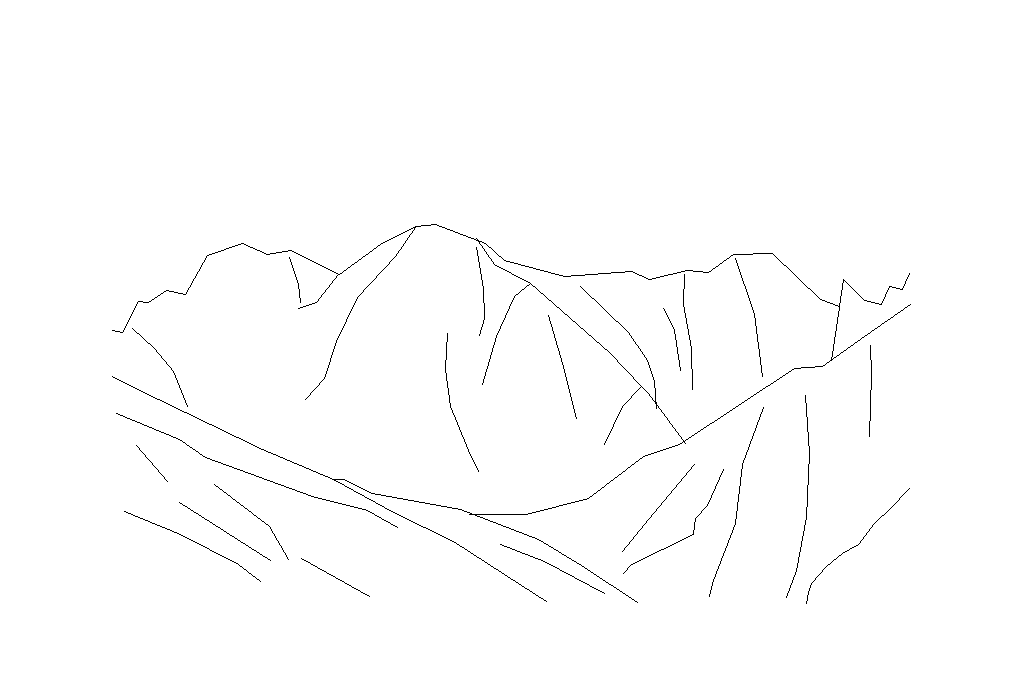

% Please make sure that the current directory is MLV_toolbox

setup

% Choose one image for demonstration
% We use data structure 11 here (row 11) and call it 'cute'!
load('dataSets/TorontoScenes/mountains_vecLD.mat');
cute = vecLD(11);

% Convert the vectorized line drawing into an image
imgLD = renderLinedrawing(cute);
figure;
imshow(imgLD);

% Compute Medial Axis
MAT = computeMAT(imgLD,28);


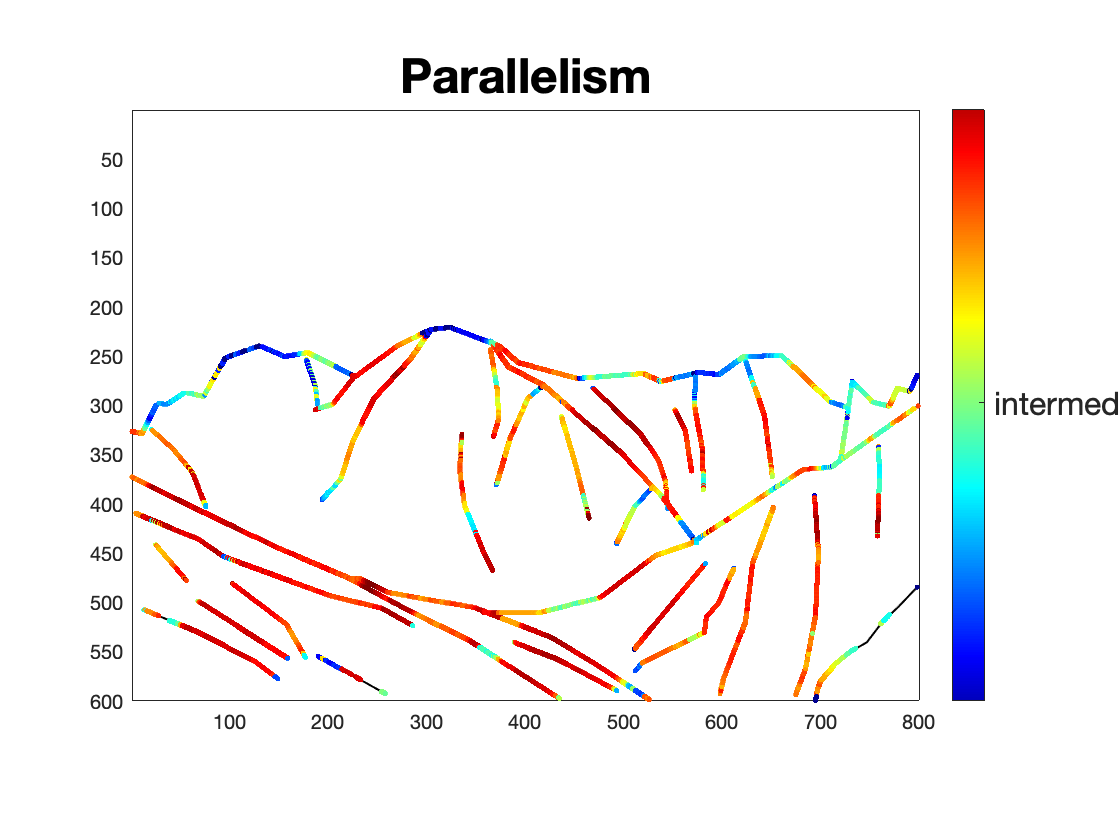

figure;
[MATcontourImages,MATskeletonImages,skeletalBranches]=computeAllMATproperties(MAT,imgLD);
drawMATproperty(MATcontourImages.mirror,cute);
title('Mirror Symmetry','FontSize',24)
drawMATproperty(MATcontourImages.parallelism,cute);
title('Parallelism','FontSize',24)